clear all
close all hidden
clc
syms  s

disp(' ======================================================.')

 ======================================================.


disp(' ')

disp(' ')

disp('Digital Control Computer Project: Final Project')

Digital Control Computer Project: Final Project


disp('Group 4 - Names: Rafael Piedade Medeiros, Gregory Williams, Somto Anyaegbu')

Group 4 - Names: Rafael Piedade Medeiros, Gregory Williams, Somto Anyaegbu


disp(' ')

disp(' ')


disp('PART 1: PID Controllers for Digital Control Systems ======')

PART 1: PID Controllers for Digital Control Systems ======


%group 4
%kh  
% your design goals are given on the project website
%your group is assigned the plant function Gp(s) given below:
zz=[    ]';
pp=[   -0.2+12i -0.2-12i  -0.1   ]';
kk=5*10^2;
Ts = 0.01;  %sample period 
fmax=100 ;   %max freq  in Hz for plotting
fmin =fmax/10^6; %min freqfor plotting
Hs = tf([1],[1]); %assume unity feedback for lag-lead or PID, but NOT used for state variable 
[tfnum,tfden] = zp2tf(zz,pp,kk)

tfnum =      0     0     0   500


tfden =     1.0000    0.5000  144.0800   14.4040


disp(' ')

disp('  ')

disp('==== plant function Gp(s):  ')

==== plant function Gp(s):  


Gps = tf(tfnum,tfden);   %plant function Gp(s)
Gp(s)= 500/(s^3+0.5*s^2+144.1*s+14.4)

$$Gp(s) = \frac{500}{s^{3}+\frac{s^{2}}{2}+\frac{1441\,s}{10}+\frac{72}{5}}$$

Gcls=feedback(Gps,Hs,-1)


Gcls =
 
                500
  -------------------------------
  s^3 + 0.5 s^2 + 144.1 s + 514.4
 
Continuous-time transfer function.



PolesGcls = pole(Gcls)

PolesGcls =    1.4243 +12.3122i
   1.4243 -12.3122i
  -3.3486 + 0.0000i


disp('  ')

disp('==== zero-order hold ZOH(s):  ')

==== zero-order hold ZOH(s):  


ZOH(s)= (1-exp(-s*Ts))/s

$$ZOH(s) = -\frac{{\mathrm{e}}^{-\frac{s}{100}}-1}{s}$$

disp('  ')

disp('====  Gc(s)=Gp(s)(1-exp(-sT0)/s:  ')

====  Gc(s)=Gp(s)(1-exp(-sT0)/s:  


Gc(s)=((1-exp(-s*Ts))/s)*Gp(s)

$$Gc(s) = -\frac{500\,\left({\mathrm{e}}^{-\frac{s}{100}}-1\right)}{s\,\left(s^{3}+\frac{s^{2}}{2}+\frac{1441\,s}{10}+\frac{72}{5}\right)}$$

disp('  ')

disp('====  Gcz(z) corresponding to Gc(s) for the appropriate sample rate of your system:  ')

====  Gcz(z) corresponding to Gc(s) for the appropriate sample rate of your system:  


tfGCz = c2d(Gps, Ts, 'zoh') %c2d translates Gp(s) x Zero-order holder to Gc(z)


tfGCz =
 
  8.317e-05 z^2 + 0.000332 z + 8.296e-05
  --------------------------------------
    z^3 - 2.981 z^2 + 2.976 z - 0.995
 
Sample time: 0.01 seconds
Discrete-time transfer function.




aug=[Ts,1]

aug =     0.0100    1.0000



disp('  ')

disp('====  Gol(w) corresponding to w transform of Gcz(z):  ')

====  Gol(w) corresponding to w transform of Gcz(z):  


%Golw = bilin(ss(tfGCz),-1,'S_Tust',aug);
%Use billingual transformation
%tfGolw = tf(Golw)

disp(' ')

disp('==== Initial uncompensated closed-loop pulse Transfer function Gcl(z) denoted Gclzinit(z) :  ')

==== Initial uncompensated closed-loop pulse Transfer function Gcl(z) denoted Gclzinit(z) :  


Gclzinit=feedback(tfGCz,Hs,-1)


Gclzinit =
 
  8.317e-05 z^2 + 0.000332 z + 8.296e-05
  --------------------------------------
    z^3 - 2.981 z^2 + 2.976 z - 0.9949
 
Sample time: 0.01 seconds
Discrete-time transfer function.




disp(' ')

disp('==== used during PID design. Set Response time to 9.76s and robust behavior factor to 0.708 in order to partially achieve design goals')

==== used during PID design. Set Response time to 9.76s and robust behavior factor to 0.708 in order to partially achieve design goals


%pidtool(tfGCz,'pidf')

disp(' ')

disp('==== The numbers below was calculated by the PID tool') 

==== The numbers below was calculated by the PID tool


KP = 0.047867

KP = 0.0479

KI = 0.0078686

KI = 0.0079

KD = -0.041025

KD = -0.0410

TF = 0.89976

TF = 0.8998


disp(' ')

disp('==== classical D(z) showing generic D(z):') 

==== classical D(z) showing generic D(z):


%Find Dz using Equation (8-65) of the textbook
Dz_PIDF = KP + (KI*Ts)*tf([1],[1 -1],Ts) + KD*tf([1 -1],[TF -TF+Ts],Ts)


Dz_PIDF =
 
  0.002044 z^2 - 0.003538 z + 0.001495
  ------------------------------------
      0.8998 z^2 - 1.79 z + 0.8898
 
Sample time: 0.01 seconds
Discrete-time transfer function.



disp(' ')

disp('==== classical D(z) showing final value form of D(z):') 

==== classical D(z) showing final value form of D(z):


Dz = zpk(Dz_PIDF) % Display D(z)


Dz =
 
  0.0022715 (z-0.9986) (z-0.7326)
  -------------------------------
         (z-1) (z-0.9889)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



disp(' ')

disp('==== classical D(z) showing generic D(z):')

==== classical D(z) showing generic D(z):


Golz=series(Dz,tfGCz) %series between Digital PID controller and Plant function in the Z domain


Golz =
 
  1.8892e-07 (z+3.724) (z-0.9986) (z-0.7326) (z+0.2678)
  -----------------------------------------------------
    (z-0.999) (z-1) (z-0.9889) (z^2 - 1.982z + 0.996)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



Cz_PIDF=feedback(Golz,Hs,-1) %creates the Feedback look Cz/Rz


Cz_PIDF =
 
    1.8892e-07 (z+3.724) (z-0.9986) (z-0.7326) (z+0.2678)
  ---------------------------------------------------------
  (z-0.991) (z^2 - 1.997z + 0.9968) (z^2 - 1.982z + 0.9961)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



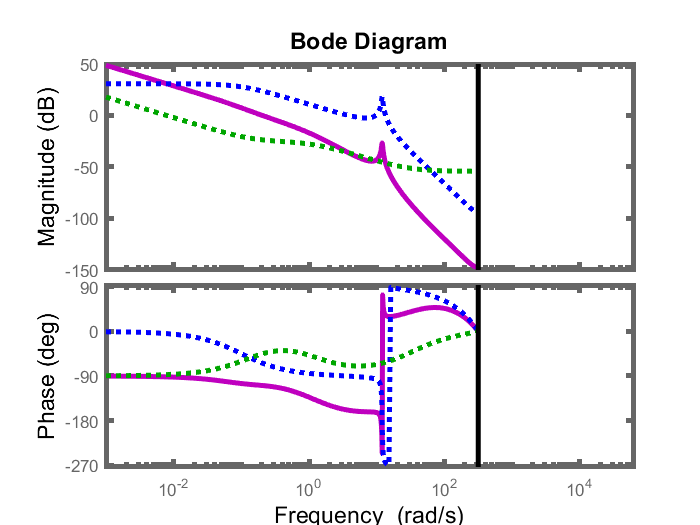


hh1=figure(1);
bplt1=bodeplot(Golz,'m',tfGCz,'b:',Dz,'g:');
setoptions(bplt1,'PhaseVisible','on','PhaseWrappingBranch',-270,'PhaseWrapping','on')
setoptions(bplt1,'FreqUnits','rad/s','XLim',10*[0.000001/Ts  62.8/Ts])
set(findall(hh1,'Type','line'),'LineWidth',3);
figax1=findall(hh1,'Type','Axes');
set(figax1(1),'LineWidth',3);set(figax1(2),'LineWidth',3);set(figax1(3),'LineWidth',3);
set(findall(hh1,'Type','text'),'FontSize',14);
set(findall(hh1,'Type','text'),'FontWeight','bold');

disp(' Fig. 1. classical design compensated |GOL(z)|=|D(z)Gcz(z)| and phase ∠GOL(z) in solid magenta color')

 Fig. 1. classical design compensated |GOL(z)|=|D(z)Gcz(z)| and phase ∠GOL(z) in solid magenta color


disp('         along with uncompensated |GOL(z)| and phase ∠GOL(z) in dashed blue color. ')

         along with uncompensated |GOL(z)| and phase ∠GOL(z) in dashed blue color. 


disp('         and along with classical design compensator |D(z)| and phase ∠D(z) in dotted green color. ')

         and along with classical design compensator |D(z)| and phase ∠D(z) in dotted green color. 


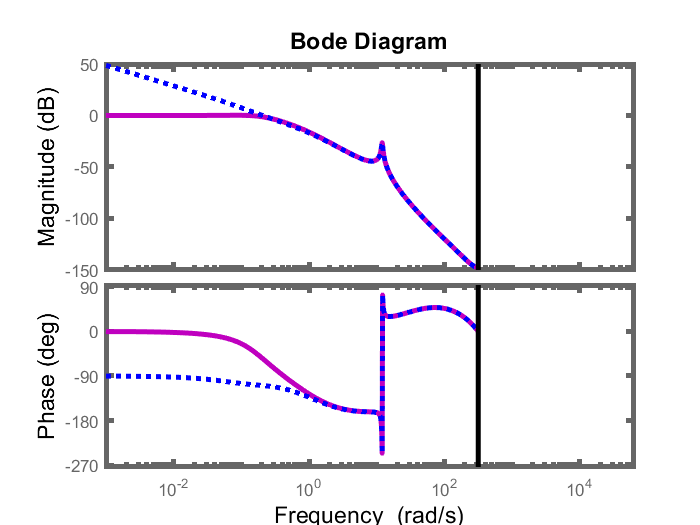


hh2=figure(2);
bplt2=bodeplot(Cz_PIDF,'m',Golz,'b:');
setoptions(bplt2,'PhaseVisible','on','PhaseWrappingBranch',-270,'PhaseWrapping','on')
setoptions(bplt2,'FreqUnits','rad/s','XLim',10*[0.000001/Ts  62.8/Ts])
set(findall(hh2,'Type','line'),'LineWidth',3);
figax2=findall(hh2,'Type','Axes');
set(figax2(1),'LineWidth',3);set(figax2(2),'LineWidth',3);set(figax2(3),'LineWidth',3);
set(findall(hh2,'Type','text'),'FontSize',14);
set(findall(hh2,'Type','text'),'FontWeight','bold');

disp(' Fig. 2. Closed-loop frequency response for classical design compensated |GCL(z)| and phase ∠GCL(z) in solid magenta color')

 Fig. 2. Closed-loop frequency response for classical design compensated |GCL(z)| and phase ∠GCL(z) in solid magenta color


disp('         Open-loop frequency response for classical design compensated |GOL(z)|=|D(z)G(z)| and phase ∠GOL(z) in dashed blue color')

         Open-loop frequency response for classical design compensated |GOL(z)|=|D(z)G(z)| and phase ∠GOL(z) in dashed blue color


disp(' ')

disp('PIDF Gain and Phase Margin:')

PIDF Gain and Phase Margin:


[Gm,Pm] = margin(Golz); GmdB = 20*log10(Gm), Pm

GmdB = 33.8955

Pm = 70.7999

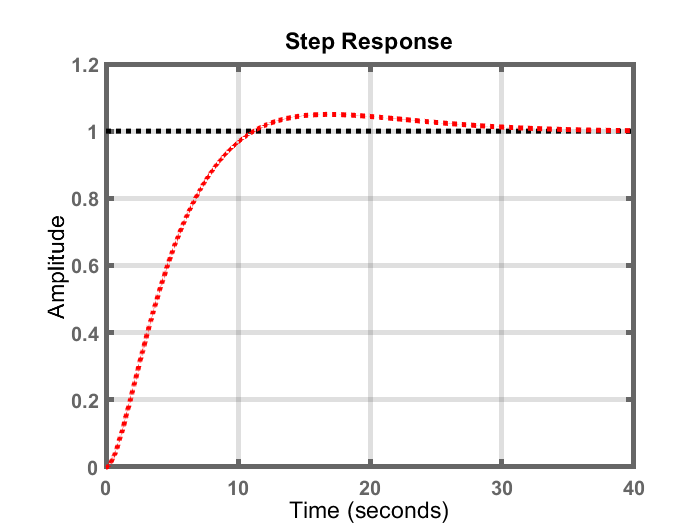


figure(3);
set(gca,'linewidth',3.0);
step(Cz_PIDF,'r:',40);
aa=gca;
aa.XGrid='on';aa.YGrid='on';aa.LineWidth=3;aa.FontWeight='bold';
aa.XLabel.FontSize=20;aa.FontSize=12;
set(findall(gcf,'Type','line'),'LineWidth',3);
set(findall(gcf,'Type','text'),'FontSize',14);
set(findall(gcf,'Type','text'),'FontWeight','bold');

disp(' Fig. 3. Closed-loop step response transient for classical design compensated')

 Fig. 3. Closed-loop step response transient for classical design compensated


disp(' ')

disp('Unit-step performance metrics for PID controller:')

Unit-step performance metrics for PID controller:


SSCT_stepinfo = stepinfo(Cz_PIDF)

SSCT_stepinfo = struct with fields:
        RiseTime: 7.2000
    SettlingTime: 26.9400
     SettlingMin: 0.9002
     SettlingMax: 1.0499
       Overshoot: 4.9863
      Undershoot: 0
            Peak: 1.0499
        PeakTime: 16.7500



disp('PART 2: State-Space Controllers for Digital Control Systems ======')

PART 2: State-Space Controllers for Digital Control Systems ======


disp('============create state-space (state-variable) model: ')

============create state-space (state-variable) model: 


disp(' ')

[A,B,C,D] = tf2ss(tfGCz.Numerator{1},tfGCz.Denominator{1});
svGc=ss(A,B,C,D,Ts) % create state-space model 


svGc =
 
  A = 
           x1      x2      x3
   x1   2.981  -2.976   0.995
   x2       1       0       0
   x3       0       1       0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
              x1         x2         x3
   y1  8.317e-05   0.000332  8.296e-05
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



svpoles=pole(svGc);
%[svpoles,svzeroes] = pzmap(tfGcz);
disp(['svGc poles=' num2str(svpoles')   ])

svGc poles=0.99083-0.11947i         0.99083+0.11947i                 0.999+0i


disp(' ')

disp('check controllability: ')

check controllability: 


contr = ctrb(A,B)   %check controllability

contr =     1.0000    2.9807    5.9086
         0    1.0000    2.9807
         0         0    1.0000


rank(contr)

ans = 3

disp(' ')

disp('check observability: ')

check observability: 


if(contr == rank(A))
disp('Given System is Controllable.');
else
disp('Given System is Uncontrollable');
end

Given System is Uncontrollable


obs=  obsv(A,C)

obs =     0.0001    0.0003    0.0001
    0.0006   -0.0002    0.0001
    0.0016   -0.0016    0.0006


rank(obs)

ans = 3

if(obs == rank(A))
disp('Given System is Observable.');
else
disp('Given System is Unobservable');
end

Given System is Unobservable


disp(' ')

disp('========Pole placement: ')

========Pole placement: 


disp('calculate location in z-plane of desired poles based on the example 9.1 of the textbook: ')

calculate location in z-plane of desired poles based on the example 9.1 of the textbook: 


tau = 0.1/5 % desire time constant

tau = 0.0200

zeta = 0.99 % desire dumping coeficient - criticaly dumped

zeta = 0.9900

rho = exp(-Ts/tau) %equation 6-10 of the textbook

rho = 0.6065

theta = sqrt((log(rho)^2)*((1/((zeta)^2))-1)) %equation 6-8 of the textbook

theta = 0.0712

[Xa,IMGa]=pol2cart(theta,rho)

Xa = 0.6050

IMGa = 0.0432


disp(' ')

disp('========Desire pole locations')

========Desire pole locations


pdesz=[complex(Xa,IMGa) complex(Xa,-IMGa) 0.08]

pdesz =    0.6050 + 0.0432i   0.6050 - 0.0432i   0.0800 + 0.0000i



disp('design controller feedback matrix/vector K: ')

design controller feedback matrix/vector K: 


disp(' ')

K = place(A,B,pdesz)

K =     1.6907   -2.5110    0.9656



disp(' ')

disp('design observer matrix/vector L based on the example 9.3 of the textbook: :  ')

design observer matrix/vector L based on the example 9.3 of the textbook: :  



%poles desired equals +&-exp(-Ts/0.007).
L = place(A',C',[0.239 -0.239 0.00008])

L = 	1.0e+04 *

    1.1460    0.5683    0.1696



regstatevarz = reg(svGc,K,L') %regulator


regstatevarz =
 
  A = 
            x1_e     x2_e     x3_e
   x1_e   0.3369    -4.27  -0.9213
   x2_e   0.5274   -1.887  -0.4714
   x3_e  -0.1411   0.4368  -0.1407
 
  B = 
                y1
   x1_e  1.146e+04
   x2_e       5683
   x3_e       1696
 
  C = 
          x1_e     x2_e     x3_e
   u1   -1.691    2.511  -0.9656
 
  D = 
       y1
   u1   0
 
Input groups:              
       Name        Channels
    Measurement       1    
                           
Output groups:          
      Name      Channels
    Controls       1    
                        
Sample time: 0.01 seconds
Discrete-time state-space model.



GCLstatevar1z=feedback(svGc,regstatevarz,1)


GCLstatevar1z =
 
  A = 
               ?        ?        ?     x1_e     x2_e     x3_e
   ?       2.981   -2.976    0.995   -1.691    2.511  -0.9656
   ?           1        0        0        0        0        0
   ?           0        1        0        0        0        0
   x1_e   0.9531    3.805   0.9507   0.3369    -4.27  -0.9213
   x2_e   0.4726    1.887   0.4714   0.5274   -1.887  -0.4714
   x3_e   0.1411   0.5632   0.1407  -0.1411   0.4368  -0.1407
 
  B = 
         u1
   ?      1
   ?      0
   ?      0
   x1_e   0
   x2_e   0
   x3_e   0
 
  C = 
               ?          ?          ?       x1_e       x2_e       x3_e
   y1  8.317e-05   0.000332  8.296e-05          0          0          0
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.




disp('pole locations of the closed loop system: ')

pole locations of the closed loop system: 


disp(' ')


disp(' ')

disp('finally add gain correction factor: ')

finally add gain correction factor: 


[num den]=ss2tf(GCLstatevar1z.A,GCLstatevar1z.B,GCLstatevar1z.C,GCLstatevar1z.D); 
svGclz=tf(num,den,Ts)


svGclz =
 
  8.317e-05 z^5 + 0.0004726 z^4 + 0.0008031 z^3 + 0.0008085 z^2 + 0.0002943 z + 3.393e-05
  ---------------------------------------------------------------------------------------
     z^6 - 1.29 z^5 + 0.4077 z^4 + 0.04422 z^3 - 0.02655 z^2 + 0.001683 z - 1.345e-07
 
Sample time: 0.01 seconds
Discrete-time transfer function.



disp(' ')

disp('check dc gain: ')

check dc gain: 


svdcgain=evalfr(GCLstatevar1z,1)

svdcgain = 0.0182

gainBlock=1/svdcgain

gainBlock = 54.8779

GCLstatevarz=series(gainBlock,GCLstatevar1z);%must use positive feedback

disp('poles and zero locations of the closed loop system: ')

poles and zero locations of the closed loop system: 


disp(' ')

svpolesNew=pole(GCLstatevarz); % compute poles
svzeroesNew=zero(GCLstatevarz); %compute zeroes
disp(['GCLstatevarz poles=' num2str(svpolesNew')   ])

GCLstatevarz poles=0.60499-0.043176i        0.60499+0.043176i                 0.239+0i                  0.08+0i                 8e-05+0i                -0.239+0i


disp(['magnitude of poles=' num2str(abs(svpolesNew'))  ])

magnitude of poles=0.60653     0.60653       0.239        0.08       8e-05       0.239


disp(['desired z-plane poles=' num2str(pdesz)   ])

desired z-plane poles=0.60499+0.043176i        0.60499-0.043176i                  0.08+0i


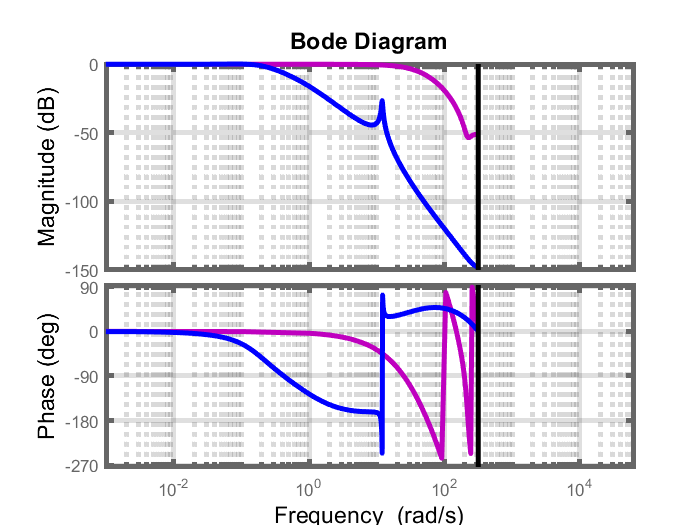



hh4=figure(4);
bplt4=bodeplot(GCLstatevarz,'m',Cz_PIDF,'b');
setoptions(bplt4,'PhaseVisible','on','PhaseWrappingBranch',-270,'PhaseWrapping','on')
setoptions(bplt4,'FreqUnits','rad/s','XLim',10*[0.000001/Ts  62.8/Ts])
grid on;
set(findall(hh4,'Type','line'),'LineWidth',3);
figax4=findall(hh4,'Type','Axes');
set(figax4(1),'LineWidth',3);set(figax4(2),'LineWidth',3);set(figax4(3),'LineWidth',3);
set(findall(hh4,'Type','text'),'FontSize',14);
set(findall(hh4,'Type','text'),'FontWeight','bold');

disp(' Fig. 4. Closed-loop frequency response for state-variable design compensated magnitude and phase in solid magenta color ')

 Fig. 4. Closed-loop frequency response for state-variable design compensated magnitude and phase in solid magenta color 


disp('         Closed-loop frequency response for classical design compensated |GCL(z)| and phase ∠GCL(z) in dashed blue color')

         Closed-loop frequency response for classical design compensated |GCL(z)| and phase ∠GCL(z) in dashed blue color


disp(' ')

disp(' ')

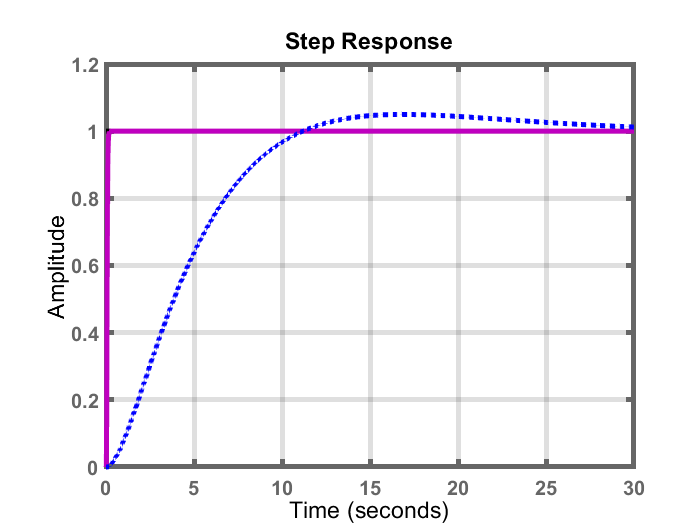


figure(5);
set(gca,'linewidth',3.0);
step(tf(GCLstatevarz),'m', Cz_PIDF,'b:',30);
aa=gca;
aa.XGrid='on';aa.YGrid='on';aa.LineWidth=3;aa.FontWeight='bold';
aa.XLabel.FontSize=20;aa.FontSize=12;
set(findall(gcf,'Type','line'),'LineWidth',3);
set(findall(gcf,'Type','text'),'FontSize',14);
set(findall(gcf,'Type','text'),'FontWeight','bold');

disp(' Fig. 5. closed-loop step response transient for state-variable design compensated in solid magenta color')

 Fig. 5. closed-loop step response transient for state-variable design compensated in solid magenta color


disp('         closed-loop step response transient for classical design compensated in dashed blue color')

         closed-loop step response transient for classical design compensated in dashed blue color


disp(' ')

disp(' ')

disp('Unit-step performance metrics for SS controller:')

Unit-step performance metrics for SS controller:


SSCTRL_stepinfo = stepinfo(GCLstatevarz)

SSCTRL_stepinfo = struct with fields:
        RiseTime: 0.0700
    SettlingTime: 0.1400
     SettlingMin: 0.9007
     SettlingMax: 1.0000
       Overshoot: 2.1771e-08
      Undershoot: 0
            Peak: 1.0000
        PeakTime: 0.4700
